# Test Limit Commands

Objective: This script tests the *limitCommands* function. It uses the kinematic equations defined in *plot_nonholonomic_kinematics* and plots limitted commands based on the allowable max wheel speed. 

Helper Functions used in this exercise:

- *plot_robot *plots the robot,  visual representation (blue arrow) of the velocity of (1) right wheel, (2) left wheel, and (3) overall velocity, and a visual representation of the resulting direction the robot will move (red line). 

Exercise:

We will use *plot_nonholonomic_kinematics *set up the kinematic equations. Go back to that file and try different values for  u_r and u_l . Pick high values for u_r and u_l to make sure we see the effects of the *limitCommands* function. 

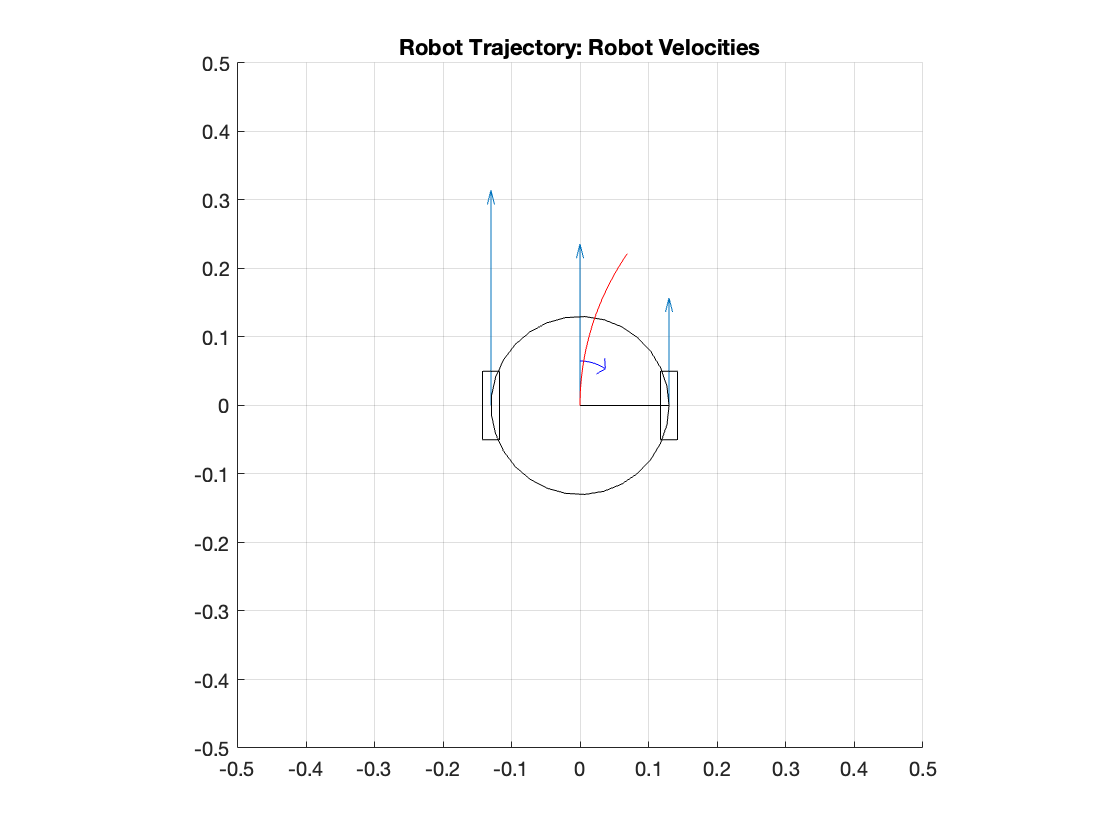

plot_nonholonomic_kinematics 

The code below, tests the limitCommands function and plots the trajectory using the new control inputs. 

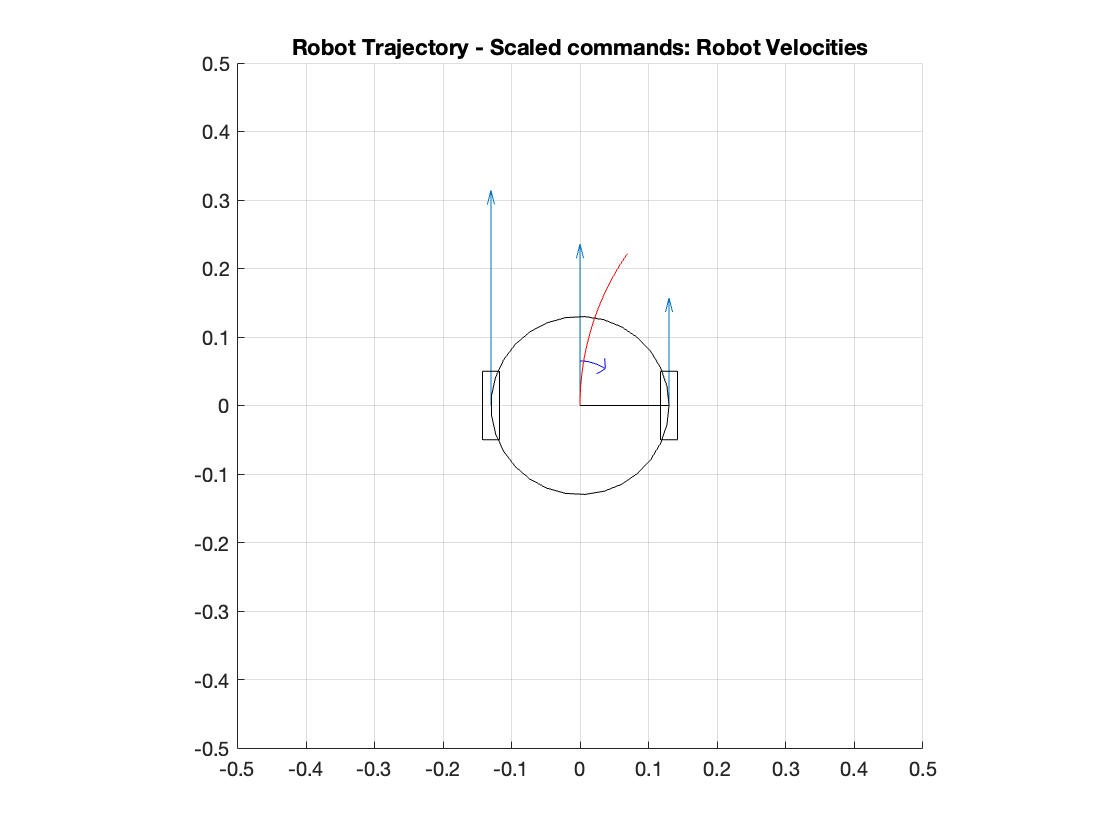

[V,omega,scaleFactor] = limitCommands(V,omega,maxWheelSpeed);
figure; 
plot_title = "Robot Trajectory - Scaled commands"; 
plot_robot(u_r,u_l,V,omega,L,r, plot_title);
set(gcf,'Visible','on')

Expected Results: This script produces two plots to compare the unscaled and scaled commands for the robot velocities. The plots should have the same curvature, however since scaled commands slow down the vehicle - the trajectory will be shorter. 

Check your Comprehension: After testing different values for  u_r and u_l, how do they relate? If you wanted to sharply turn in one direction how would you set  u_r and u_l?If you wanted to move forward, how would you set  u_r and u_l? Why does it make more sense to command the Create using V and w rather than  u_r and u_l?